# Unit Testing

The goal is to test the graphical App of the Parking Meter system.

## 1. Clean Session

Clear all remaining variables, figures and timers:

clear variables; close all; clc;
try
  stop(timerfind);
  delete(timerfind);
catch
  disp('No timers are running.');
end

No timers are running.


Add needed classes to the import list:

import matlab.unittest.TestRunner;
import matlab.unittest.TestSuite;
import matlab.unittest.plugins.TestReportPlugin;
import matlab.unittest.plugins.CodeCoveragePlugin;

## 2. Test Runner and Test Suite

Build test runner and test suite allowing to customize how the suite is run and which tests to run.

runner = TestRunner.withTextOutput;

Test report format:

reportName = 'Report';
reportType = 'pdf';
switch (reportType)
  case 'docx'
    reportPlugin = TestReportPlugin.producingDOCX([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'html'
    reportPlugin = TestReportPlugin.producingHTML([reportName '.' reportType],...
                                                  'IncludingPassingDiagnostics',true,...
                                                  'IncludingCommandWindowText',true);
  case 'pdf'
    reportPlugin = TestReportPlugin.producingPDF([reportName '.' reportType],...
                                                 'IncludingPassingDiagnostics',true,...
                                                 'IncludingCommandWindowText',true);
  otherwise
    error('Unsupported file type for a report.');
end
runner.addPlugin(reportPlugin);

Coverage report:

coveragePlugin = CodeCoveragePlugin.forFile('..\Component\ParkingMeterGUI.mlapp');
runner.addPlugin(coveragePlugin);

Create the test suite from the defined test class

classSuite = TestSuite.fromClass(?TestApp);

## 3. Initialization

Preparing the parking meter system for the tests:

global UNIT_TESTING; %#ok<GVMIS> 
% Set to true if the MATLAB unit testing API is used, otherwise always false
UNIT_TESTING = true;
% Close any potential running instance of the low-level application
if (system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &') ~= 0)
  fprintf('No running instance of the low-level application has been detected.\n');
end

No running instance of the low-level application has been detected.


% Call the low-level MATLAB code of the application in a separate process
fprintf('Starting the low-level application instance...\n');

Starting the low-level application instance...


system('..\\Component\\UnitTesting\\ParkingMeterProject.exe&');

## 4. Run Tests

Running TestApp
. Processing the test case #1...

Verification failed in TestApp/testCase_1_StraightTicketPurchase.
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyEqual failed.
    --> Sizes do not match.
        
        Actual size:
             6     2
        Expected size:
             7     2
    
    Actual Value:
      6×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {' '   }    {'0.20'}
        {' '   }    {'0.10'}
        {'---' }    {' '   }
    Expected Value:
      7×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {' '   }    {'0.50'}
        {' '   }    {'0.20'}
        {' '   }    {'0.10'}
        {'---' }    {' '   }
    ------------------
    Stack Information:
    ------------------
    In D:\GitHub\C_Code_Integration\M

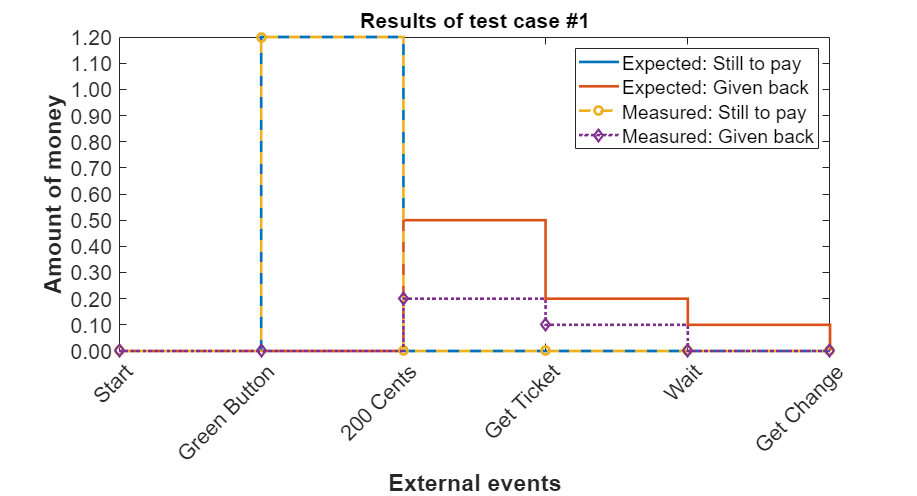


[Terse] Diagnostic logged (2022-06-10 19:43:29):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_b94ea52c-b90e-4dbf-a152-3cfa5f1cd04c.fig
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_b94ea52c-b90e-4dbf-a152-3cfa5f1cd04c.png
. Processing the test case #2...


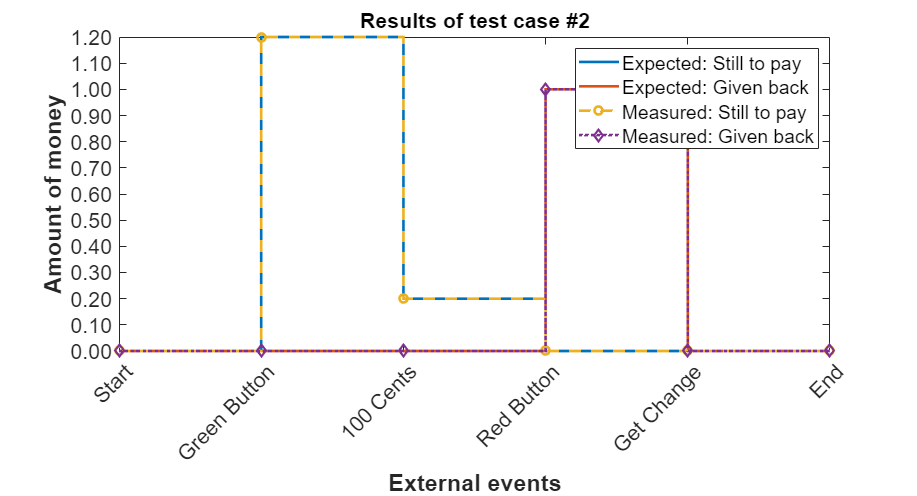


[Terse] Diagnostic logged (2022-06-10 19:43:54):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_57070635-10d1-4cc4-aa62-aa63ebda9450.fig
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_57070635-10d1-4cc4-aa62-aa63ebda9450.png
. Processing the test case #3...

Verification failed in TestApp/testCase_3_BiggestChangeOnTicketPurchase.
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyEqual failed.
    --> Sizes do not match.
        
        Actual size:
             9     2
        Expected size:
            10     2
    
    Actual Value:
      9×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {'0.20'}    {' '   }
        {'0.10'}    {' '   }
        {' '   }    {'0.50'}
        {' '   }    {'0.20'}
        {' '   }    {'

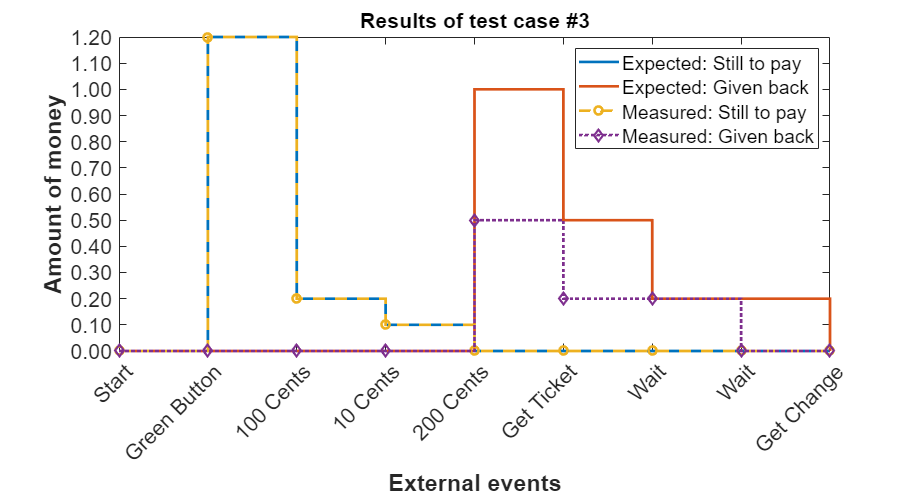


[Terse] Diagnostic logged (2022-06-10 19:44:26):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_5bfd7d01-5922-49f9-bf31-ec3b25f5253e.fig
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_5bfd7d01-5922-49f9-bf31-ec3b25f5253e.png
. Processing the test case #4...

Verification failed in TestApp/testCase_4_FullyEmptyAndReloadCashBox.
    ---------------------
    Framework Diagnostic:
    ---------------------
    verifyEqual failed.
    --> Sizes do not match.
        
        Actual size:
            27     2
        Expected size:
            31     2
    
    Actual Value:
      27×2 cell array
    
        {'DISP'}    {'COIN'}
        {'---' }    {' '   }
        {'1.20'}    {' '   }
        {'0.20'}    {' '   }
        {'0.10'}    {' '   }
        {' '   }    {'0.50'}
        {' '   }    {'0.20'}
        {' '   }    {'0.

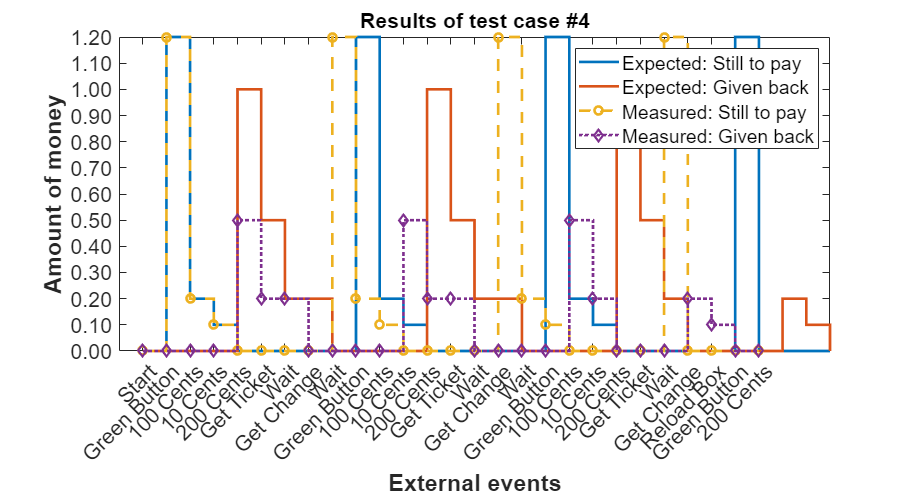


[Terse] Diagnostic logged (2022-06-10 19:46:02):
Figure saved to:
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_aabed520-31bf-4319-a7b8-74eb3f632932.fig
--> C:\Users\sebas\AppData\Local\Temp\260d4500-8e98-48a6-a7c5-285272cb7451\Figure_aabed520-31bf-4319-a7b8-74eb3f632932.png
.
Done TestApp
__________

Failure Summary:

     Name                                              Failed  Incomplete  Reason(s)
     TestApp/testCase_1_StraightTicketPurchase           X                 Failed by verification.
    -----------------------------------------------------------------------------------------------
     TestApp/testCase_3_BiggestChangeOnTicketPurchase    X                 Failed by verification.
    -----------------------------------------------------------------------------------------------
     TestApp/testCase_4_FullyEmptyAndReloadCashBox       X 

% Call the unit testing framework for automated testing
results = runner.run(classSuite);

% Close the running instance of the low-level application
system('taskkill /F /im ParkingMeterProject.exe /im cmd.exe &');

## 5. Results Summary

disp(results.table);

                            Name                            Passed    Failed    Incomplete    Duration      Details   
    ____________________________________________________    ______    ______    __________    ________    ____________

    {'TestApp/testCase_1_StraightTicketPurchase'       }    false     true        false        30.129     {1×1 struct}
    {'TestApp/testCase_2_CancelTicketPurchase'         }    true      false       false        24.414     {1×1 struct}
    {'TestApp/testCase_3_BiggestChangeOnTicketPurchase'}    false     true        false        31.687     {1×1 struct}
    {'TestApp/testCase_4_FullyEmptyAndReloadCashBox'   }    false     true        false        95.887     {1×1 struct}

